# Speech Command Recognition with MATLAB/PyTorch Co-Execution -- Calling MATLAB from Python

## Overview

This demo shows how to develop a deep learning model to recognize speech commands in audio using a combination of MATLAB and PyTorch, for users who require the use of PyTorch to design and train the deep learning model. The reference MATLAB-only example can be found at [Speech Command Recognition Using Deep Learning](https://www.mathworks.com/help/audio/ug/Speech-Command-Recognition-Using-Deep-Learning.html).

This demo explains how to co-execute MATLAB and PyTorch based on the following key assumptions:

- The deep learning model architecture and the training loop are implemented in PyTorch.

- MATLAB is used to ingest and preprocess the Speech Commands Dataset [1], augment the training data with pitch shifting, and extract Mel spectrograms features from the augmented speech data. 

- Python is used as a master environment, calling out to MATLAB through the [MATLAB Engine API for Python](https://www.mathworks.com/help/matlab/matlab-engine-for-python.html).

- After performing training, you will import the trained network to MATLAB using [importONNXNetwork](https://www.mathworks.com/help/deeplearning/ref/importonnxnetwork.html).

The figure below summarizes the flow. Pointers to the individual code files are provided in the following sections.

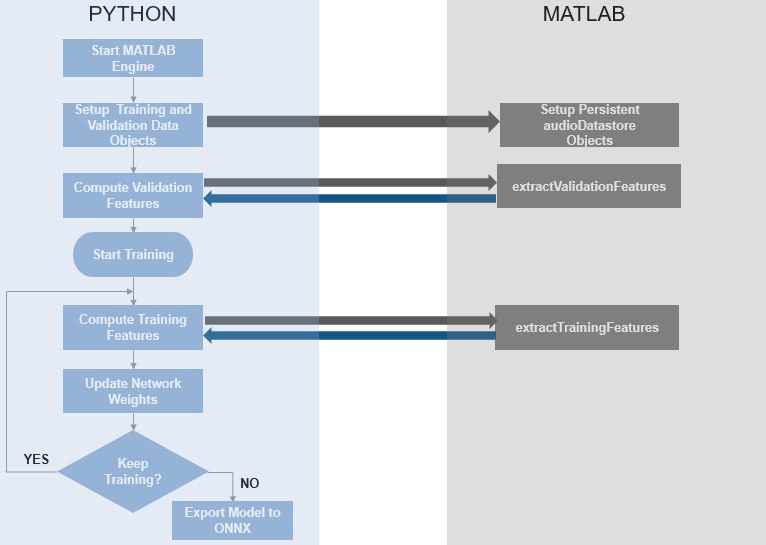

## Environment Setup

Refer to the steps outlined in [SetupNotes.mlx](matlab:open('./SetupNotes.mlx')) (Using Python as master environment) to ensure your environment is correctly set up.

Ensure the folder containing all helper code files is on your MATLAB path.

addpath("HelperFiles")

## Top-level demo files 

#### PyTorch Master Training Script

Use the Python script [coxecutionExamplePyTorch.py](matlab:open('./HelperFiles\coexecutionExamplePyTorch.py')) to train the neural network. The script:

- Starts the MATLAB Engine to execute MATLAB commands from Python. Learn more on [MATLAB Engine API for Python](https://www.mathworks.com/help/matlab/matlab-engine-for-python.html).

- Creates a PyTorch DataLoader object to iterate through the training dataset. In this example, the Python code relies on MATLAB for dataset preparation and management. This is accomplished by calling the MATLAB function [setupDatasets.m](matlab:open('./HelperFiles\setupDatasets.m')) that ingests and preprocesses the dataset for this specific application. **This file needs to be initialized with the path to the dataset from your system**. More information on this below.

- Creates another PyTorch DataLoader object for the Validation Features and Labels mainly using the MATLAB function [extractValidationFeatures.m](matlab:open('./HelperFiles\extractValidationFeatures.m')). Validation features are extracted from the significantly smaller validation data, can usually be extracted in one step and kept in memory to monitor the accuracy of the model at each training epoch. Note that extractValidationFeatures.m leverages [audioFeatureExtractor](https://www.mathworks.com/help/audio/ref/audiofeatureextractor.html) via the additional helper function [helperExtractAuditoryFeatures.m](matlab:open('./HelperFiles\helperExtractAuditoryFeatures.m')) to compute Mel spectrograms. To speed up processing, it also distributes feature extraction across available CPU cores using tall arrays.

- Defines a deep learning model as a convolutional network in PyTorch. The network is equivalent to the one defined using MATLAB in the example [Speech Command Recognition Using Deep Learning](https://www.mathworks.com/help/deeplearning/ug/deep-learning-speech-recognition.html).

- Trains the network via implementing a model training loop, where gradient descent is performed on each training minibatch to update the model weights. The network accuracy is measured against the validation data at the end of each epoch. In the training loop, PyTorch gets a new minibatch of training features from MATLAB by invoking [extractTrainingFeatures.m](matlab:open('./HelperFiles\extractTrainingFeatures.m')). extractTrainingFeatures.m is used in trainLoader, to create all mini batches. It reads a mini-batch of pre-selected training audio files, it augments the source data and it transforms it into Mel spectrograms. More details below.

- Exports the trained model to the ONNX at the end of each training epoch. ONNX (Open Neural Network eXchange) is a format which MATLAB can then import for further testing and real-time implementation.

#### MATLAB Testing Script

Once the pre-trained model is available in ONNX format, the following MATLAB script shows how to import it, test it and implement it in real time (e.g. on a RaspberryPi board) while exploiting the same data processing code used previously for training:

open importDeployPretrainedOnnxModel.mlx

## Details on MATLAB Helper Functions

#### Dataset Setup

To run the demo you need to first download and extract the data set [1] on a local folder.

url = 'https://ssd.mathworks.com/supportfiles/audio/google_speech.zip';
downloadFolder = tempdir;
dataFolder = fullfile(downloadFolder,'google_speech');

if ~exist(dataFolder,'dir')
    disp('Downloading data set (1.4 GB) ...')
    unzip(url,downloadFolder)
end

Once the dataset archive is extracted locally, open the file setupDataset.m

edit setupDatasets.m

and ensure the variable `datafolder` points to the root folder of the dataset.

The function setupDatasets.m:

- Creates an [audioDatastore](https://www.mathworks.com/help/audio/ref/audiodatastore.html) that points to the entire data set.

- Uses the audioDatastore subset method to create a smaller datastore for the purposes of this example

- Breaks up the large dataset into training and validation audioDatastore objects.

The training and validation datastores are defined as persistent, so they will be available throughout the application and will not be re-created.

#### Feature Extraction During Training

To understand more closely how signals features are extracted from the dataset and fed to network training in the loop, inspect the function extractTrainingFeatures.m:

edit extractTrainingFeatures.m

This function:

- Reads a mini-batch of audio files from the persistent training audioDatastore, as provided in turn by setupDatasets.m

- It performs data augmentation through [audioDataAgumenter](https://www.mathworks.com/help/audio/ref/audiodataaugmenter.html) using random pitch shifting 

- It computes Mel spectrograms from the augmented speech signals using [audioFeatureExtractor](https://www.mathworks.com/help/audio/ref/audiofeatureextractor.html) via the helper function. helperExtractAuditoryFeatures

- While performing audio augmentation and feature extraction, it distributes computations across multiple CPU cores using |tall| arrays to speed up processing

- Shuffles the training datastore at the end of each epoch

## References

[1] Warden P. "Speech Commands: A public dataset for single-word speech recognition", 2017. Available from [https://storage.googleapis.com/download.tensorflow.org/data/speech_commands_v0.01.tar.gz](https://storage.googleapis.com/download.tensorflow.org/data/speech_commands_v0.01.tar.gz). Copyright Google 2017. The Speech Commands Dataset is licensed under the Creative Commons Attribution 4.0 license, available here: [https://creativecommons.org/licenses/by/4.0/legalcode.](https://creativecommons.org/licenses/by/4.0/legalcode.)

*Copyright 2019-2021 The MathWorks, Inc.*